%C:\Users\andre\CoRSoC\PLUTOSamples
clear all
% List of .mat files
files = {'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet1.mat',
    'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet2.mat', 
    'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet3.mat'}

files = 3×1 cell array
    {'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet1.mat'}
    {'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet2.mat'}
    {'C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet3.mat'}



% Number of samples to keep per set
num_samples_per_subset = 2048 * 16

num_samples_per_subset = 32768

count_data_fields = 0;
idxs_samples_per_set = 1:num_samples_per_subset;
data_samples = [];
count = 0;

% Struct to hold all combined and extracted data
for i = 1:length(files)
    file_name = files{i};
    data = load(file_name);
    vars = fieldnames(data);
    for j = 1:length(vars)
        var_name = vars{j};
        % Check if variable name starts with 'samples'
        if startsWith(var_name, 'samples')
            data_subset = data.(var_name);
            % Keep first num_samples_per_subset
            data_samples = [data_samples data_subset(idxs_samples_per_set)];
        end
    end
end
numel(data_samples)

ans = 1769472

numel(data_samples)/2048

ans = 864

size(data_samples)

ans =            1     1769472


% Convert to timeseries
fs = 16e6; % Sampling f
dt = 1/fs; % Time step
time_vec = (0:length(data_samples)-1)*dt

time_vec =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ts_data_samples = timeseries(data_samples, time_vec)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [1769472x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x1769472 double]
        DataInfo: 

save('PLUTO_TEST_DATA_TS.mat', 'ts_data_samples')
save('PLUTO_TEST_DATA.mat', 'data_samples')

% Intermidetate Test Stimulus
clear all
load('C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet1.mat')
load('C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet2.mat')
load('C:\Users\andre\CoRSoC\IPs\Stimulus\SampleSet3.mat')
%V1
% data_samples = [samples0001_0_1(1:2048*16) samples0001_20_1(1:2048*16)]
% data_samples = [data_samples samples0010_0_1(1:2048*16) samples0010_20_1(1:2048*16)]
% data_samples = [data_samples samples0100_0_1(1:2048*16) samples0100_20_1(1:2048*16)]
% data_samples = [data_samples samples1000_0_1(1:2048*16) samples1000_20_1(1:2048*16)]
%V2
% data_samples = [samples0001_0_1(1:2048*16) samples0001_0_2(1:2048*16)]
% data_samples = [data_samples samples0001_20_1(1:2048*16) samples0001_20_2(1:2048*16)]
% data_samples = [data_samples samples0010_0_1(1:2048*16) samples0010_0_2(1:2048*16)]
% data_samples = [data_samples samples0010_20_1(1:2048*16) samples0010_20_2(1:2048*16)]
%V3
% data_samples = [samples0001_0_1(1:2048*16) samples0001_0_2(1:2048*16)]
% data_samples = [data_samples samples0001_20_1(1:2048*16) samples0001_20_2(1:2048*16)]
% data_samples = [data_samples samples0010_0_1(1:2048*16) samples0010_0_2(1:2048*16)]
% data_samples = [data_samples samples0010_20_1(1:2048*16) samples0010_20_2(1:2048*16)]
% data_samples = [data_samples samples0100_0_1(1:2048*16) samples0100_0_2(1:2048*16)]
% data_samples = [data_samples samples0100_20_1(1:2048*16) samples0100_20_2(1:2048*16)]
% data_samples = [data_samples samples1000_0_1(1:2048*16) samples1000_0_2(1:2048*16)]
% data_samples = [data_samples samples1000_20_1(1:2048*16) samples1000_20_2(1:2048*16)]
%V4
% data_samples = [samples0001_0_1(1:2048*16) samples0001_0_2(1:2048*16)]
% data_samples = [data_samples samples0001_20_1(1:2048*16) samples0001_20_2(1:2048*16)]
% data_samples = [data_samples samples0010_0_1(1:2048*16) samples0010_0_2(1:2048*16)]
% data_samples = [data_samples samples0010_20_1(1:2048*16) samples0010_20_2(1:2048*16)]
% data_samples = [data_samples samples0100_0_1(1:2048*16) samples0100_0_2(1:2048*16)]
% data_samples = [data_samples samples0100_20_1(1:2048*16) samples0100_20_2(1:2048*16)]
% data_samples = [data_samples samples1000_0_1(1:2048*16) samples1000_0_2(1:2048*16)]
% data_samples = [data_samples samples1000_20_1(1:2048*16) samples1000_20_2(1:2048*16)]
% data_samples = [data_samples samples1100_0_1(1:2048*16) samples1100_0_2(1:2048*16)]%no 20
% data_samples = [data_samples samples0011_0_1(1:2048*16) samples0011_0_2(1:2048*16)]
% data_samples = [data_samples samples0011_20_1(1:2048*16) samples0011_20_2(1:2048*16)]
% data_samples = [data_samples samples0110_0_1(1:2048*16) samples0110_0_2(1:2048*16)]
% data_samples = [data_samples samples0110_20_1(1:2048*16) samples0110_20_2(1:2048*16)]
% data_samples = [data_samples samples1001_0_1(1:2048*16) samples1001_0_2(1:2048*16)]
% data_samples = [data_samples samples1001_20_1(1:2048*16) samples1001_20_2(1:2048*16)]
% data_samples = [data_samples samples1111_0_1(1:2048*16) samples1111_0_2(1:2048*16)]
% data_samples = [data_samples samples1111_20_1(1:2048*16) samples1111_20_2(1:2048*16)]
%V5
data_samples = [samples0001_0_1(1:2048*4) samples0001_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0001_20_1(1:2048*4) samples0001_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0010_0_1(1:2048*4) samples0010_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0010_20_1(1:2048*4) samples0010_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0100_0_1(1:2048*4) samples0100_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0100_20_1(1:2048*4) samples0100_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1000_0_1(1:2048*4) samples1000_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1000_20_1(1:2048*4) samples1000_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1100_0_1(1:2048*4) samples1100_0_2(1:2048*4)]%no 20

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0011_0_1(1:2048*4) samples0011_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0011_20_1(1:2048*4) samples0011_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0110_0_1(1:2048*4) samples0110_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples0110_20_1(1:2048*4) samples0110_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1001_0_1(1:2048*4) samples1001_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1001_20_1(1:2048*4) samples1001_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1111_0_1(1:2048*4) samples1111_0_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i


data_samples = [data_samples samples1111_20_1(1:2048*4) samples1111_20_2(1:2048*4)]

data_samples =    0.3536 + 0.3536i  -1.0607 + 0.0000i   0.3536 + 0.0000i   0.3536 + 0.3536i  -1.4142 + 0.0000i   1.0607 - 0.3536i  -0.7071 + 0.3536i   0.3536 - 0.3536i   0.3536 + 0.7071i  -0.3536 + 0.7071i   0.0000 + 0.3536i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.3536 - 0.7071i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.7071 - 0.3536i  -0.3536 + 0.7071i  -0.3536 - 0.7071i   0.3536 + 0.3536i  -0.7071 - 0.3536i   0.3536 - 1.4142i   0.3536 + 0.3536i  -0.3536 - 0.3536i   0.7071 + 0.3536i   0.3536 - 0.7071i   0.0000 + 0.7071i  -0.3536 - 0.3536i   0.3536 - 0.3536i  -0.3536 + 0.0000i   0.0000 - 0.7071i   0.3536 + 0.3536i  -0.3536 + 0.3536i   0.3536 - 0.3536i  -0.3536 + 1.0607i  -0.3536 - 0.3536i   0.3536 + 0.0000i   0.0000 + 0.3536i  -0.3536 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.3536i  -0.7071 - 0.3536i   0.3536 + 0.3536i   0.0000 + 0.0000i   0.0000 - 0.3536i   0.3536 + 0.3536i  -0.7071 + 0.7071i   0.7071 - 0.3536i   0.3536 + 1.0607i





num_samples = numel(data_samples)

num_samples = 278528

% Convert to timeseries
fs = 16e6; % Sampling f
dt = 1/fs; % Time step
time_vec = (0:length(data_samples)-1)*dt

time_vec =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ts_data_samples = timeseries(data_samples, time_vec)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [278528x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x278528 double]
        DataInfo: 


% Parameters
N = 2048; 
n = 0:N-1;
    
% Windows
Hanning = 0.5 * (1 + cos(2*pi*n/N));
Norm_Han = sum(Hanning);

ts_data_samples = open('PLUTO_TEST_DATA_TS.mat').ts_data_samples;
num_samples = numel(ts_data_samples.Data)

num_samples = 331776

N = 2048

N = 2048

n=0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


Num_Segments = num_samples/N

Num_Segments = 162

data_array = ts_data_samples.Data

data_array = data_array(:,:,1) =

   0.0000 - 0.8944i


data_array(:,:,2) =

   0.0000 + 0.0000i


data_array(:,:,3) =

   0.3536 - 0.3536i


data_array(:,:,4) =

  -0.3536 + 0.7071i


data_array(:,:,5) =

   0.4851 + 0.0000i


data_array(:,:,6) =

   0.0000 + 0.0000i


data_array(:,:,7) =

   0.7428 - 1.1142i


data_array(:,:,8) =

   0.6860 + 0.3430i


data_array(:,:,9) =

   0.4714 + 0.4714i


data_array(:,:,10) =

   0.0000 + 0.4851i


data_array(:,:,11) =

   0.0000 + 0.5547i


data_array(:,:,12) =

  -0.2981 + 0.2981i


data_array(:,:,13) =

   0.0000 - 0.4851i


data_array(:,:,14) =

   0.0000 + 0.9701i


data_array(:,:,15) =

   0.7845 + 0.7845i


data_array(:,:,16) =

  -0.3430 + 0.6860i


data_array(:,:,17) =

   0.0000 + 0.5000i


data_array(:,:,18) =

  -0.4714 + 0.4714i


data_array(:,:,19) =

  -0.2857 + 0.0000i


data_array(:,:,20) =

  -1.1926 + 0.5963i


data_array(:,:,21) =

   0.4472 + 0.0000i


data_array(:,:,22) =

   0.0000 - 0.4472i


data_array(:,:,23) =

   0.0

data_array = data_array(:)'

data_array =    0.0000 + 0.8944i   0.0000 + 0.0000i   0.3536 + 0.3536i  -0.3536 - 0.7071i   0.4851 + 0.0000i   0.0000 + 0.0000i   0.7428 + 1.1142i   0.6860 - 0.3430i   0.4714 - 0.4714i   0.0000 - 0.4851i   0.0000 - 0.5547i  -0.2981 - 0.2981i   0.0000 + 0.4851i   0.0000 - 0.9701i   0.7845 - 0.7845i  -0.3430 - 0.6860i   0.0000 - 0.5000i  -0.4714 - 0.4714i  -0.2857 + 0.0000i  -1.1926 - 0.5963i   0.4472 + 0.0000i   0.0000 + 0.4472i   0.0000 - 0.2828i  -0.5657 - 0.8485i  -0.4714 + 0.4714i   0.4714 + 0.0000i  -0.4650 - 0.9300i  -0.4650 + 0.4650i   0.0000 + 0.0000i   0.0000 - 0.4714i   0.6576 - 0.3288i  -0.3714 - 0.3714i   0.0000 + 0.0000i  -0.4851 - 0.4851i   0.2774 - 0.2774i  -0.5657 + 0.0000i   0.0000 + 0.4472i   0.0000 - 0.4714i   0.5547 - 0.5547i  -0.5657 + 0.0000i  -0.2481 + 0.0000i  -0.2357 - 0.2357i  -0.2857 + 0.2857i  -0.2828 + 0.2828i  -0.4961 + 0.4961i   0.0000 + 0.4961i  -0.2357 + 0.0000i   0.0000 + 0.9428i  -0.4714 + 0.0000i   0.4472 - 0.4472i


time_array = ts_data_samples.Time'

time_array =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


time_array = time_array(:)

time_array =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


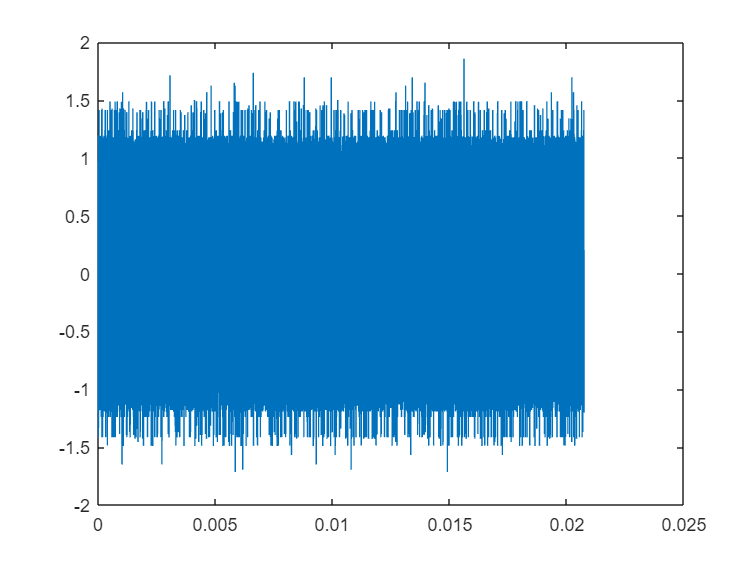

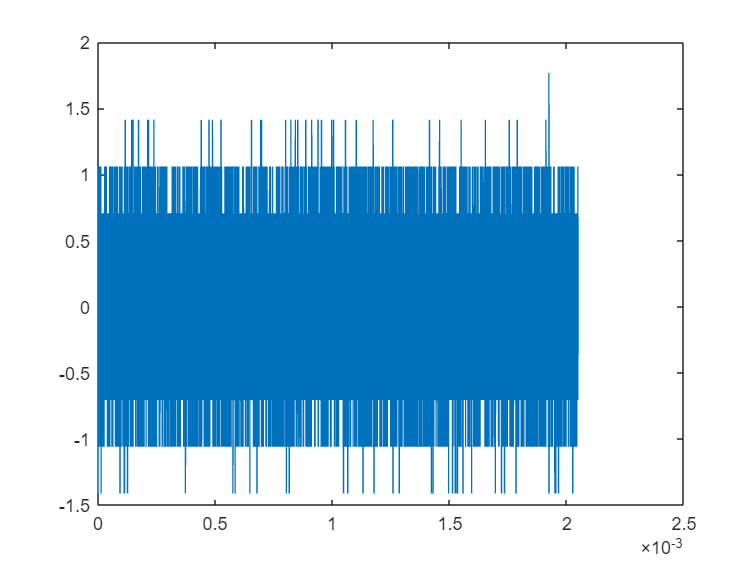


figure;
plot(time_array, data_array)

figure;
plot(abs(fft(data_array)))

% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,num_samples/fs,Num_Segments)

t_axis_1N =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0030    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054    0.0055    0.0057    0.0058    0.0059    0.0061    0.0062    0.0063


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.1288    0.2576    0.3864    0.5152    0.6440    0.7728    0.9016    1.0304    1.1592    1.2880    1.4167    1.5455    1.6743    1.8031    1.9319    2.0607    2.1895    2.3183    2.4471    2.5759    2.7047    2.8335    2.9623    3.0911    3.2199    3.3487    3.4775    3.6063    3.7351    3.8639    3.9926    4.1214    4.2502    4.3790    4.5078    4.6366    4.7654    4.8942    5.0230    5.1518    5.2806    5.4094    5.5382    5.6670    5.7958    5.9246    6.0534    6.1822    6.3110


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344    0.2422    0.2500    0.2578    0.2656    0.2734    0.2812    0.2891    0.2969    0.3047    0.3125    0.3203    0.3281    0.3359    0.3438    0.3516    0.3594    0.3672    0.3750    0.3828


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =    -8.0000   -7.9922   -7.9844   -7.9766   -7.9688   -7.9609   -7.9531   -7.9453   -7.9375   -7.9297   -7.9219   -7.9141   -7.9062   -7.8984   -7.8906   -7.8828   -7.8750   -7.8672   -7.8594   -7.8516   -7.8438   -7.8359   -7.8281   -7.8203   -7.8125   -7.8047   -7.7969   -7.7891   -7.7812   -7.7734   -7.7656   -7.7578   -7.7500   -7.7422   -7.7344   -7.7266   -7.7188   -7.7109   -7.7031   -7.6953   -7.6875   -7.6797   -7.6719   -7.6641   -7.6562   -7.6484   -7.6406   -7.6328   -7.6250   -7.6172


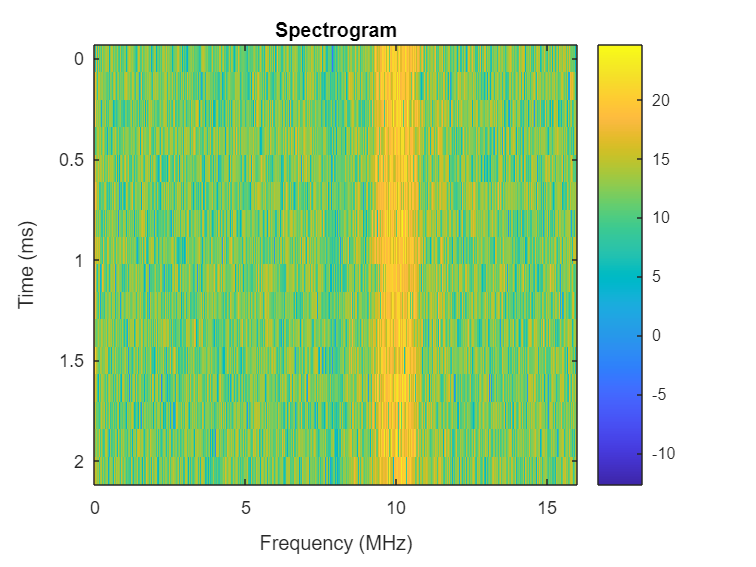


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);   
    Data(i,:) = 10*log10(abs(fft(data_array(index),N)));
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

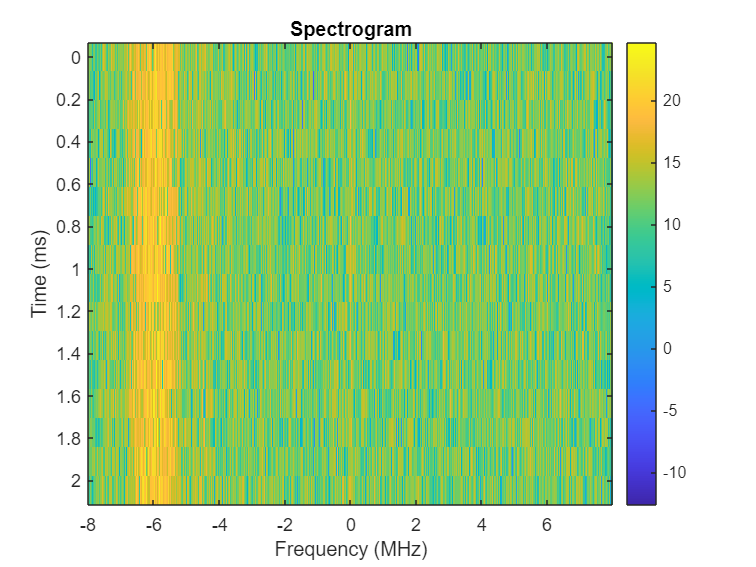

figure;
imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar